# Exercises:

1. Plot the next function(piecewise) : 


$$\[ \begin{cases} 
      x^{2} - x +3 & -2\leq x< 2 & \text{and x} \in[-2:0.05:1] \\
      2x  + 1 & 2\leq x < 4  & \text{and x} \in[2.5:0.01:4] \\
   \end{cases}
\]$$


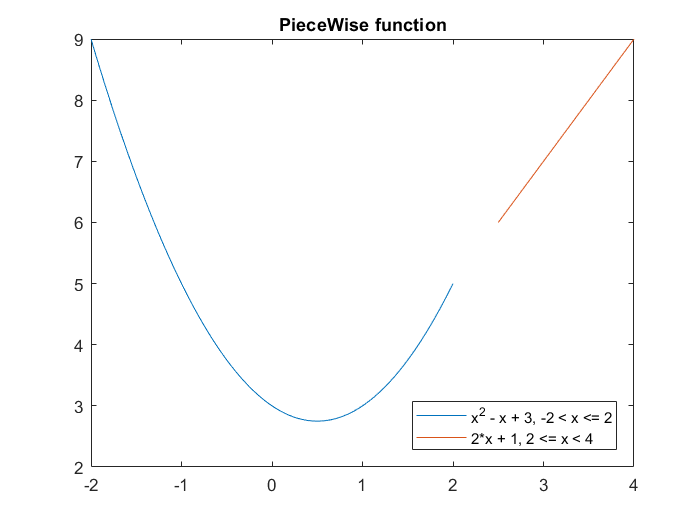

x1 = -2:0.05:2;
x2 = 2.5:0.01:4;

f1 = x1.^2 - x1 + 3;
f2 = 2*x2 +1;

figure,
plot(x1,f1); hold on;
plot(x2,f2); hold off;
title('PieceWise function');
legend('x^2 - x + 3, -2 < x <= 2', '2*x + 1, 2 <= x < 4','Location','SouthEast');

2. Plot on two charts in the same frame the functions:


$$y = x^2 -3x -2 \\ 
z = x^3 - 2x +1 \\
\text{x} \in [-5:0.02:5] \\
$$


The first one with a green continuous line, and the other one with a blue discontinuous line. Mark with a plus red mark the point $(2,1)$ in both charts.

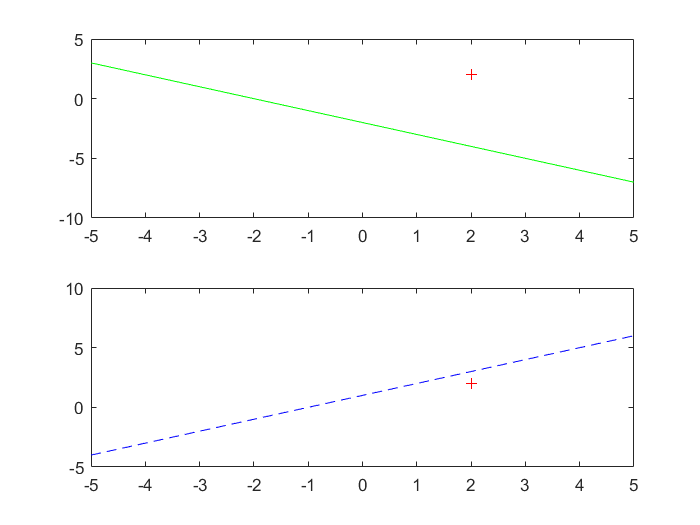

x = -5:0.02:5;
y = 2*x - 3*x -2 ;
z = 3*x - 2*x + 1 ;

figure,
subplot(2,1,1), plot(x,y,'g'),hold on;
plot(2,2,'+r'), 
subplot(2,1,2), plot(x,z,'--b'),hold on; 
plot(2,2,'+r'), 

3. Open the image **"spine.tif" **and add *Pepper and salt noise.* 


A = imread('spine.tif');
% B(:,:,4) =[];
S = imnoise(A,'salt & pepper',0.1);
h1 = fspecial('average');
h2 = fspecial('gaussian');
media = imfilter(S,h1);
gauss = imfilter(S,h2);
mediana = medfilt2(S);

Then apply the fiters you learned in the previous exercises.

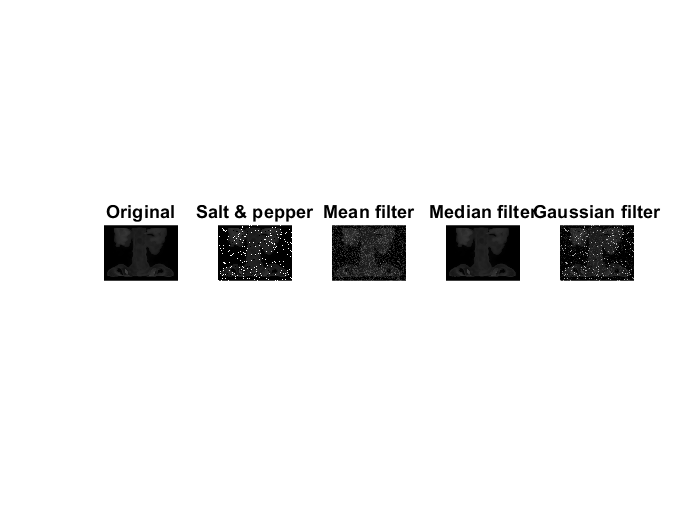


subplot(1,5,1),imshow(A),title('Original');
subplot(1,5,2),imshow(S),title('Salt & pepper');
subplot(1,5,3),imshow(media),title('Mean filter');
subplot(1,5,4),imshow(mediana),title('Median filter');
subplot(1,5,5),imshow(gauss),title('Gaussian filter');

3.1 Which one best reduces noise?

disp("The median filter")

The median filter


4. Now open the image **"peppers.png"** add *Gaussian  noise.*

A = imread('spine.tif');
Sg = imnoise(A,'gaussian',0.1);

h1 = fspecial('average');
h2 = fspecial('gaussian');

media = imfilter(Sg,h1);
gauss = imfilter(Sg,h2);
mediana = medfilt2(Sg);

Then apply the same filters as before.

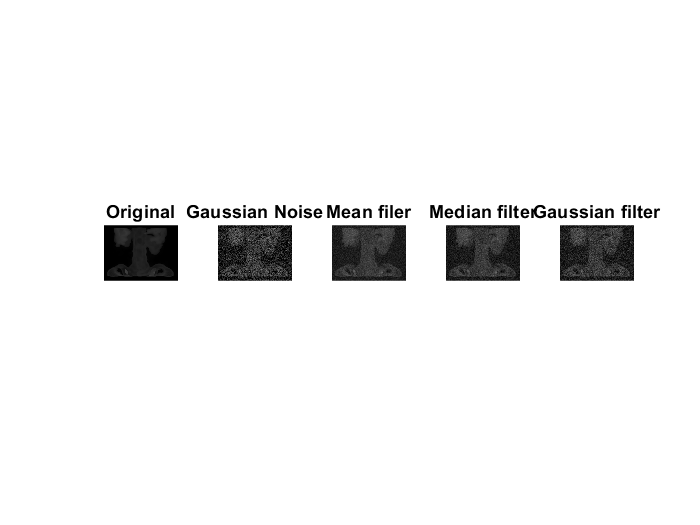


figure,
subplot(1,5,1), imshow(A),title('Original');
subplot(1,5,2), imshow(Sg),title('Gaussian Noise');
subplot(1,5,3), imshow(media),title('Mean filer');
subplot(1,5,4), imshow(mediana), title('Median filter');
subplot(1,5,5), imshow(gauss), title('Gaussian filter');

Which one best reduces noise?

disp("In this case, the mean and median filter works better with this specific " + ...
    "noise/filter configurations despite being Gaussian noise.")

The mean and median filter works better with this specific noise configuration despite being Gaussian noise.


What happened with histograms?

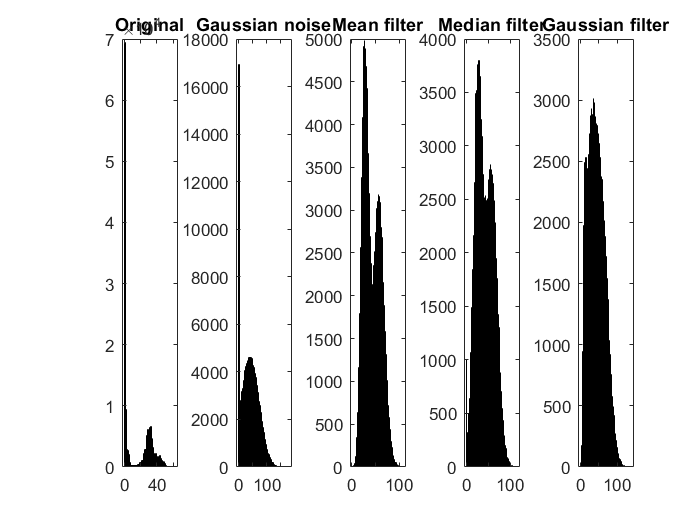

figure,
subplot(1,5,1), histogram(A),title('Original');
subplot(1,5,2), histogram(Sg),title('Gaussian noise');
subplot(1,5,3), histogram(media),title('Mean filter');
subplot(1,5,4), histogram(mediana), title('Median filter');
subplot(1,5,5), histogram(gauss), title('Gaussian filter');

How you can see, The Gaussian filter fails reducing the high frequencies, keeping the noise produced by the gaussian noise and reducing so much the low ones. Meanwhile the others keeps better the original shape of the image wihout the gaussian noise.